The following script creates the data we're going to use in this demonstration. Data structure can be examined in the script.

clear
create_test_data;

Create a net and store the data inside.

net = Hopfieldnet(size(A));
data = cat(3,T, A);
net.store(data);

Take one of the stored images and add noise. The intensity here is the probability of flipping a pixel

noise_intensity = 0.2;
noisy_data = A;
for i = 1:size(noisy_data,1)
    for j = 1:size(noisy_data,2)
        if rand() <= noise_intensity
            noisy_data(i,j) = -noisy_data(i,j);
        end
    end
end

Run the network on the noisy data. Plot the network state every n iterations to monitor activity

iterations = 10000;
disp('noisy image')

noisy image


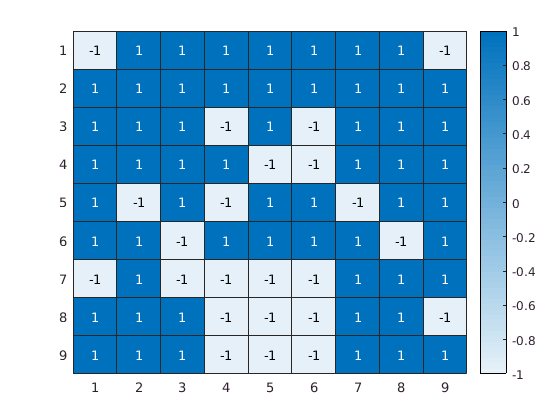

net.run(0, noisy_data)
net.plotstate

disp('recalled image')

recalled image


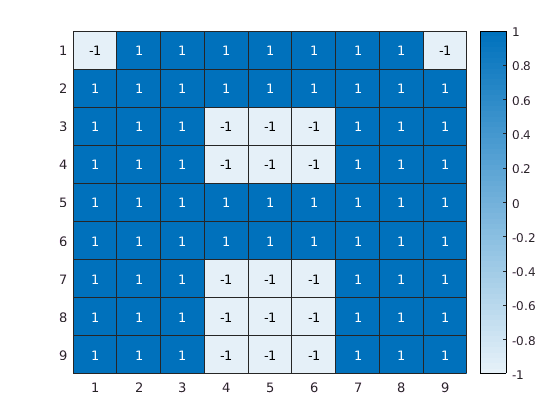

net.run(iterations)
net.plotstate